Estimate impulse response

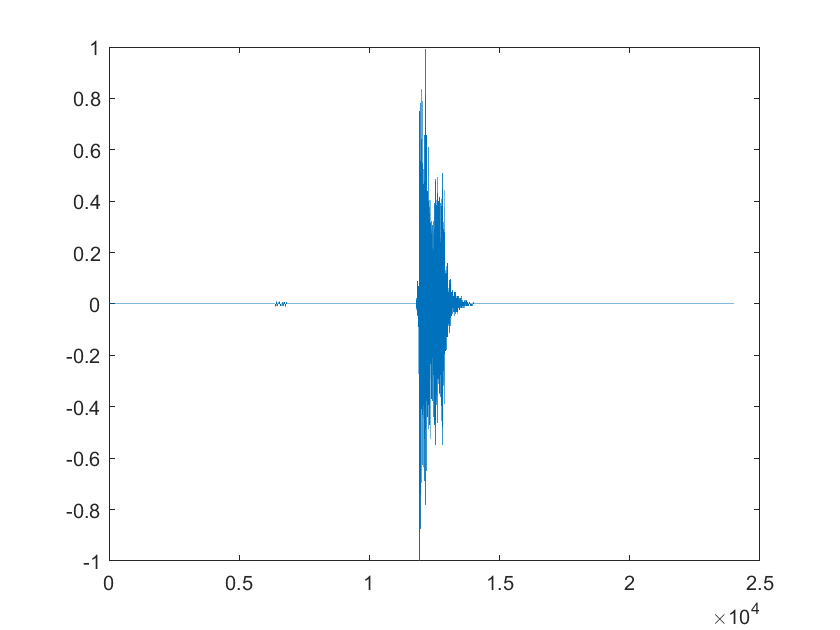

% recObj = audiorecorder;
% disp('start receiving.');
% recordblocking(recObj, 3);
% disp('end receiving');
% h_received = getaudiodata(recObj);
plot(h_received);

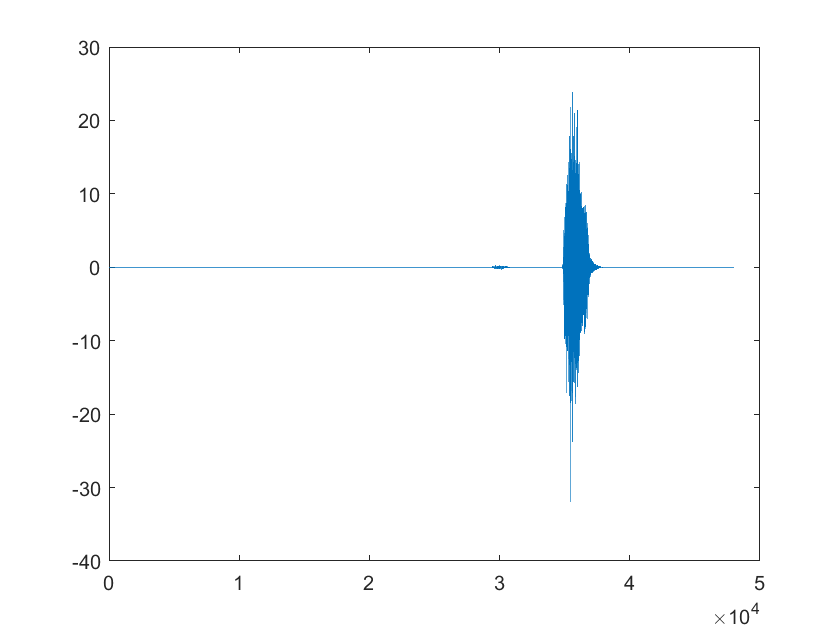

h_xcorr = xcorr(h_received, n);
plot(h_xcorr)

for i=1:size(h_xcorr)
    if h_xcorr(i) > 1
        break
    end
end
for j=size(h_xcorr):-1:1
    if h_xcorr(j) > 1
        break
    end
end
h = h_xcorr(i:j)

h =     1.2131
    1.2010
   -0.0725
    0.3224
   -0.1037
   -1.6572
   -2.5563
   -2.2311
   -0.4965
    1.6319


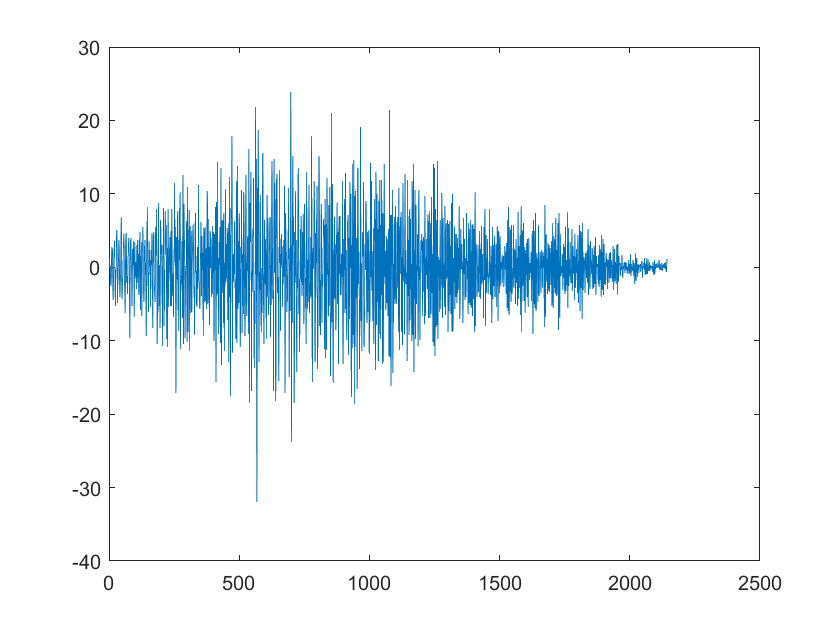

plot(h)

Text decoding

% recObj = audiorecorder;
% disp('start receiving.');
% recordblocking(recObj, 8);
% disp('end receiving');
% y = getaudiodata(recObj);
% plot(y);

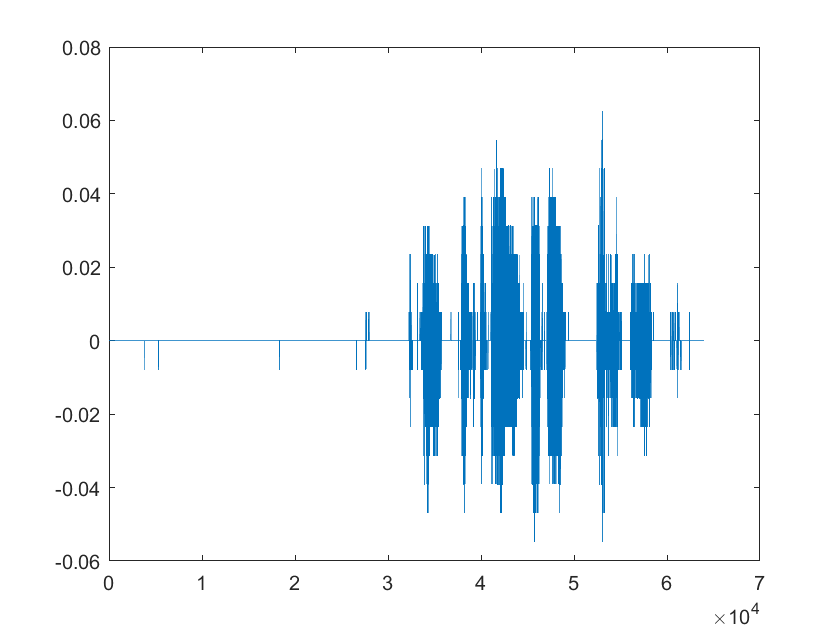

plot(y);

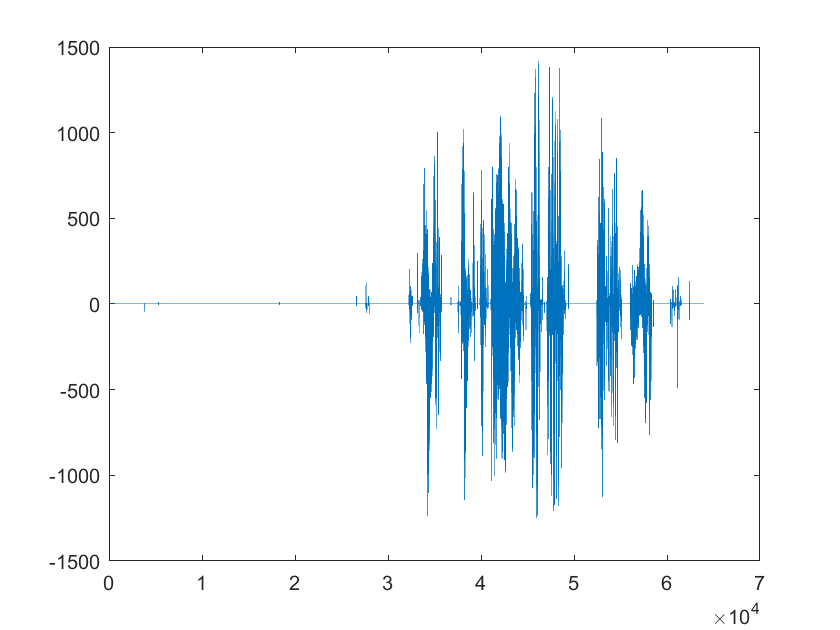

fc = 2000; %2kHz
time = linspace(0,1,length(y));
y_c = y.*cos(2*pi*fc*time.');
y_s = y.*sin(2*pi*fc*time.')*j;
y_b = y_c + y_s;
y_b = lowpass(y_b, fc, 44.1e3);
plot(y_b);

for i=1:size(y_b)
    if y_b(i) > .25*10^4
        y_b(i) = 1;
    elseif y_b(i) < -.25*10^4
        y_b(i) = -1;
    else
        y_b(i) = 0;
    end
end
y_b = nonzeros(y_b);
for i=1:size(y_b)
    if y_b(i) == -1
        y_b(i) = 0;
    end
end
binary = num2str(y_b(1:5243));

Index exceeds the number of array elements (0).

binary = binary(binary~=' ');
mess = char(bin2dec(reshape(binary,7,[]).').')
plot(y_b);

n: input white noise

h_received: received response from white noise input

h: estimated channel response

y: received response from encoded text message